# Text classification

The code below recreates (approximately) the data preparation and classifier training steps from the spam/ham example in chapter 4 of the Brett Lantz book to solve a new problem: classifying between written reports describing different types of failure events in a factory. The challenge is to i) explain what the existing code does by adding comments; ii) extend the code to evaluate the performance of the classifier on the testing data.

Marks are available for:

- Commenting the existing code. Remember good comments should explain the *why* rather than the *what*, so, for example, a comment like "remove stop words" above a function called `removeStopWords()` would receive no credit. [9 marks]

- Preparing and encoding the testing data using the bag of words that is generated by the existing code [6 marks]

- Predicting class labels for the encoded testing data, and generating a visualisation of the resulting confusion matrix where appropriate colours are used to represent the different matrix elements [5 marks]

[Total: 20 marks]

%loading up the dataset to use 
data = readtable('factoryReports.csv');
%shuffle the data
data = data(randperm(size(data,1)),:);
%create a testing dataset and training dataset
data_train = data(1:380, :);
data_test = data(381:480, :);
%separate the labels and example for the testing dataset
test_labels = data_test{:,1};
test_examples = data_test{:,2};
%separte the labels and examples for the training dataset
train_labels = data_train{:,1};
train_examples = data_train{:,2};
%convert the data text to lower case
data_c = lower(data_t);
%creating an array of words containing the training examples text
data_t = tokenizedDocument(train_examples);
%clean the date text from stop words such as "there", etc to remove noise
%from data
data_c = removeStopWords(data_c);
%clean data from punctuation
data_c = erasePunctuation(data_c);
%grouping together the forms of the words so they can be analysed aa a
%signle item
data_c = normalizeWords(data_c);
%create a bag-of-words model keeping all the different words without taking
%into account the gramatic or order of the words in the text but keeping
%their meaning
bag = bagOfWords(data_c);
%remove words from the bag that do not appear more than 4 times
bag = removeInfrequentWords(bag, 4);

% train a Naive Bayes classifier (no further comments required):
m = fitcnb(bag.Counts, train_labels, 'DistributionNames','mn');


% add as many lines of code as you need below:
%prepare the testing data
%convert the data text to lower case
data_lc = lower(data_test);
%creating an array of words containing the testing examples text
data_test_array = tokenizedDocument(test_examples);
%clean the date text from stop words such as "there", etc to remove noise
%from data
data_test_array = removeStopWords(data_test_array);
%clean data from punctuation
data_test_array = erasePunctuation(data_test_array);
%grouping together the forms of the words so they can be analysed aa a
%signle item
data_test_array = normalizeWords(data_test_array);
%create a bag-of-words model keeping all the different words without taking
%into account the gramatic or order of the words in the text but keeping
%their meaning
bag_test = bagOfWords(data_test_array);
%remove words from the bag that do not appear more than 4 times
bag_test = removeInfrequentWords(bag_test, 4);
%encode the testing data
enc_test = encode(bag,data_test_array);

%predict the class labels
predictions = predict (m,enc_test);
% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =      0     9     2     1
     2    25    14     2
     1    13    23     0
     0     2     5     1


order = 4×1 cell array
    {'Leak'              }
    {'Mechanical Failure'}
    {'Electronic Failure'}
    {'Software Failure'  }


% calculate the overall classification accuracy:
acc = sum(diag(c)) / sum(c(1:1:end))

acc = 0.4900

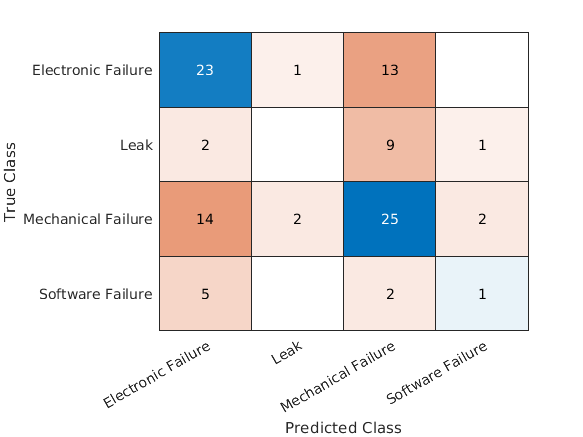

% output a labelled chart of the confusion matrix:
c_chart = confusionchart(test_labels, predictions);